# Square

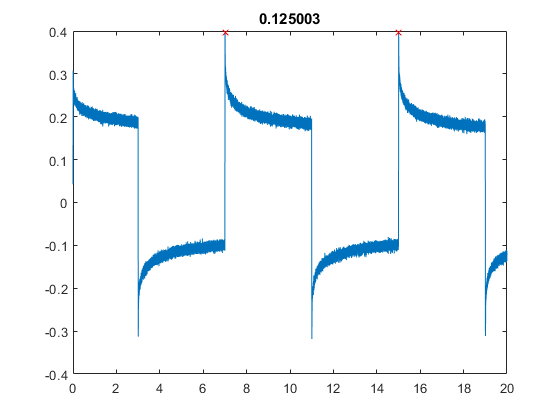

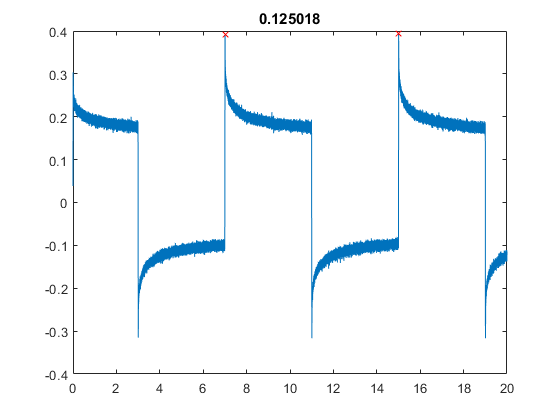

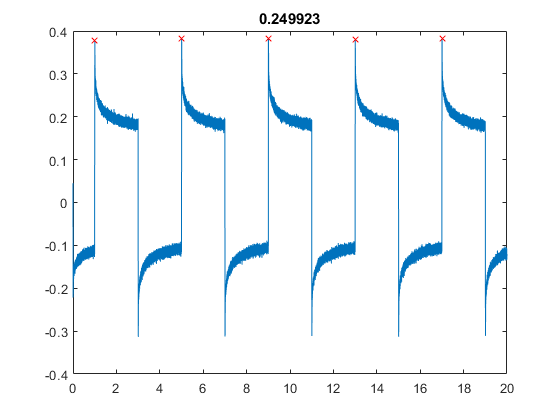

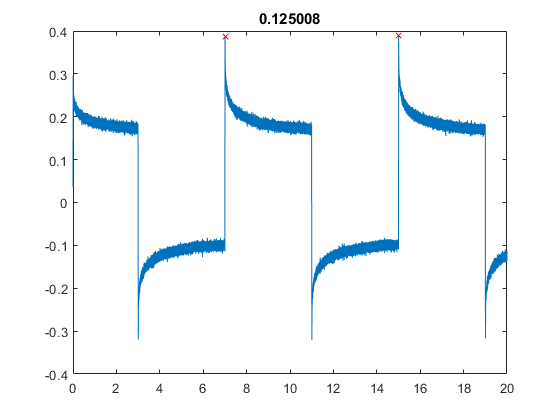

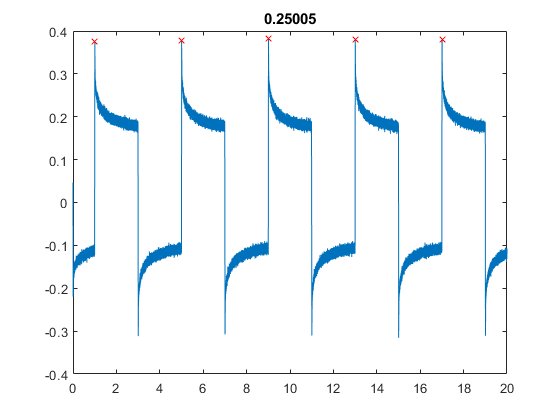

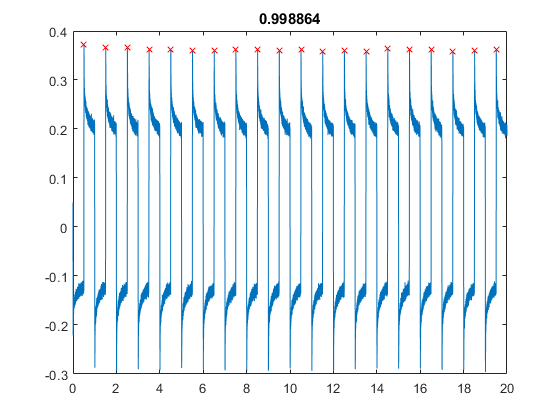

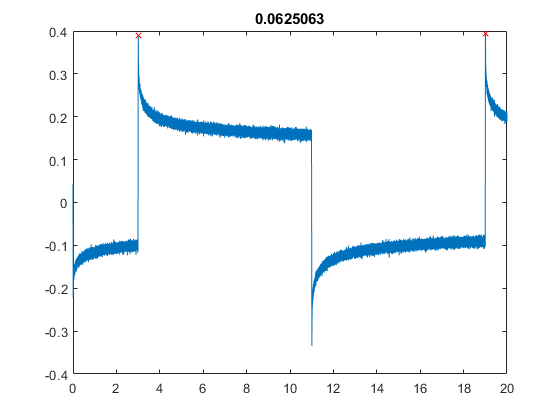

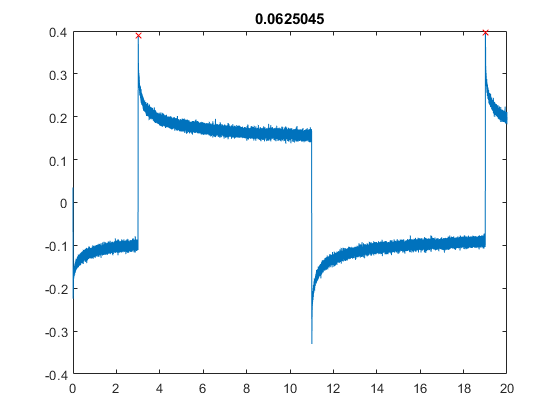

Index exceeds the number of array elements (1).


freq = [];
k=1;
for i=1:single_trial_length:length(stim_fb)
    trial = stim_fb(i+start_stim:i+single_trial_length-start_stim);
    [pks,locs] = findpeaks(trial, fs, "MinPeakProminence", 0.05, "MinPeakHeight", 0.8*max(trial));
    freq(k) = 1/diff(locs(1:2));
    
    
    total_dur = ON_dur+2*OFF_dur;
    t = 0:1/fs:ON_dur;
    figure;
    plot(t,trial, locs, pks, 'rx');
    title(freq(k));
    k=k+1;
end

## sine

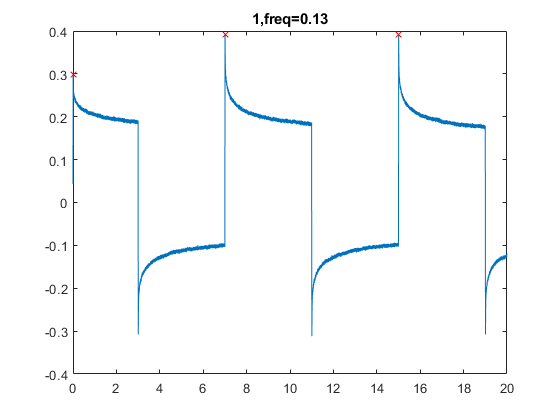

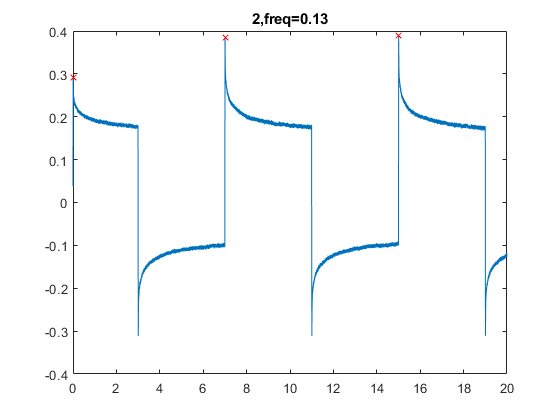

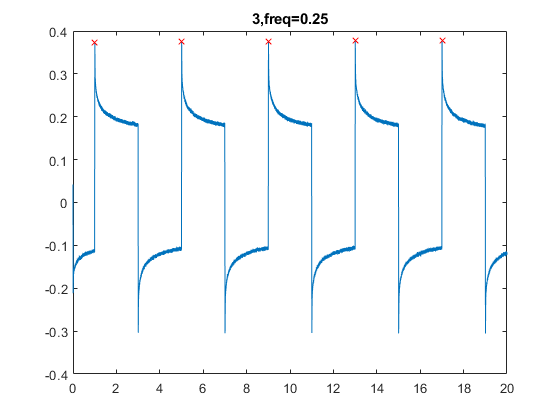

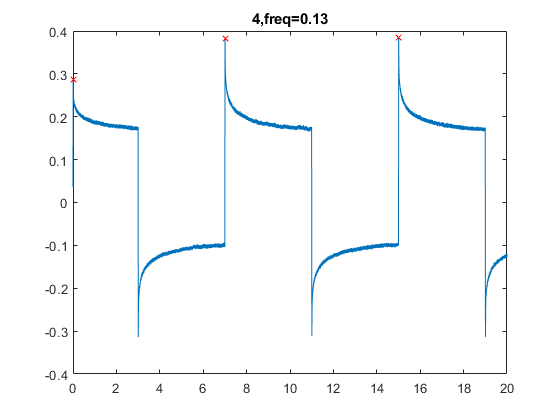

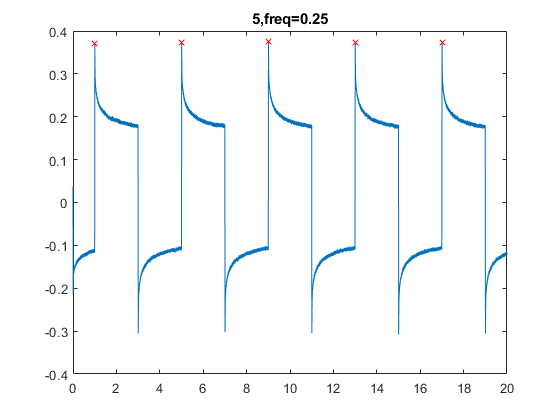

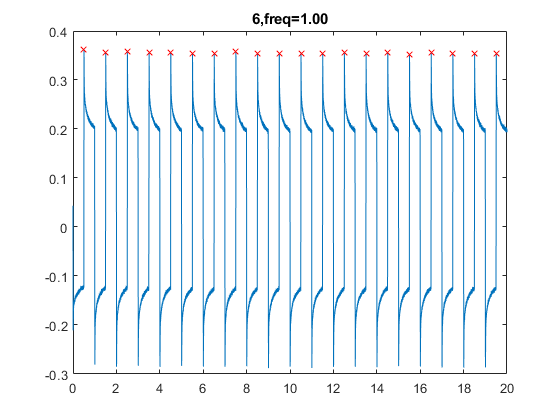

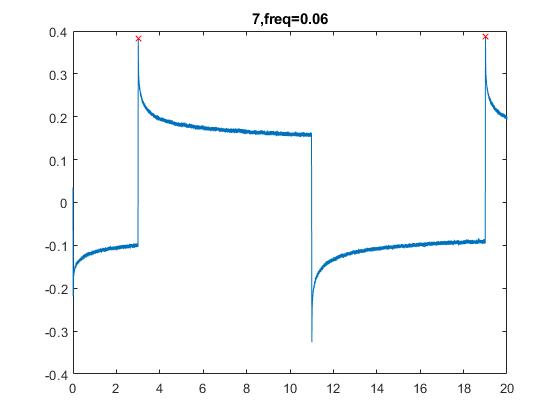

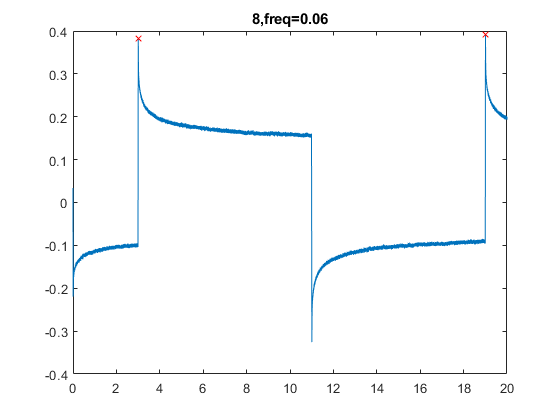

Index exceeds the number of array elements (120000050).

freq = [];
k=1;

for i=1:single_trial_length:length(stim_fb)
    trial = stim_fb(i+start_stim:i+single_trial_length-start_stim);
    trial_filt = sgolayfilt(trial, 4, 51);
    [pks,locs] = findpeaks(trial_filt, fs, "MinPeakProminence", 0.05, "MinPeakHeight", 0.6*max(trial));
    freq(k) = 1/mean(diff(locs));
    
    
    total_dur = ON_dur+2*OFF_dur;
    t = 0:1/fs:ON_dur;
    figure;
            plot(t,trial_filt, locs, pks, 'rx');
%     xlim([6 8]);
    titlestr = sprintf("%d,freq=%0.02f",k,freq(k));
    title(titlestr);
    k=k+1;
end

   
freq = round(freq, 2);